clc; clear all; close all
%------------- global variables----------------
global gamma
global rho_inf
global a_ref
global Cd
global thrust
global grav
global Isp
global T
global r 
global rho_inf 
global re
global eps
global Cl
% ------------------ Given---------------------
Cl = 0.1411;
Cd = 0.0921;
re = 6378 * 10^3 ; % meters
rho_inf = 0.11628; % kg/m^3
grav = 9.805; % m/s^2 
a_ref = 0.32893; %
t_span = 0:0.1:130

t_span =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


T  = 22250

T = 22250

gamma = 1.4

gamma = 1.4000

mach = 6;
R = 287.05;
vel = mach * sqrt(gamma * R * T)

vel = 1.7942e+04

Isp = 310;
temp = 216.65;
% --------------variables --------------------
eps = 45;
g_2 = 45;


x0 = [1100, 0 ,vel, 0 ,g_2,0 ,18168, 0]

x0 = 1.0e+04 *

    0.1100         0    1.7942         0    0.0045         0    1.8168         0


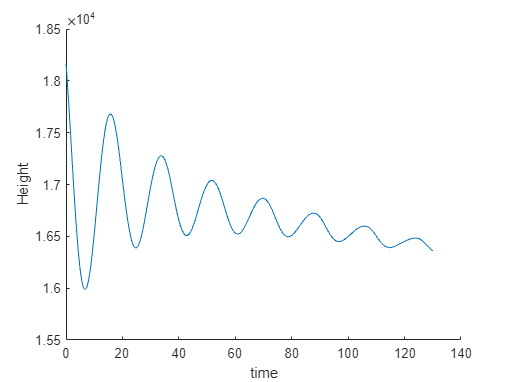

%   [x0(1) x0(2) x0(3) x0(4) x0(4) x0(4) x0(7) x0(8)]
%   [m0    m1    v     v1    g     g1    h     h1]

[t,x]=ode45('EOM_full', t_span, x0);

figure 
hold on
xlabel('time')
ylabel('Height')
plot(t(1:end,:),x(1:end,7))
hold off

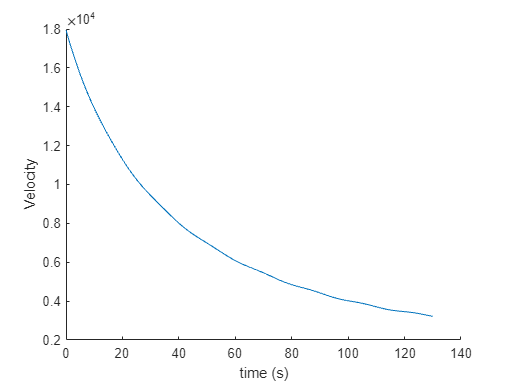


figure
hold on 
ylabel('Velocity')
xlabel('time (s)')
plot(t(1:end,:),x(1:end,3)) % velocity
hold off

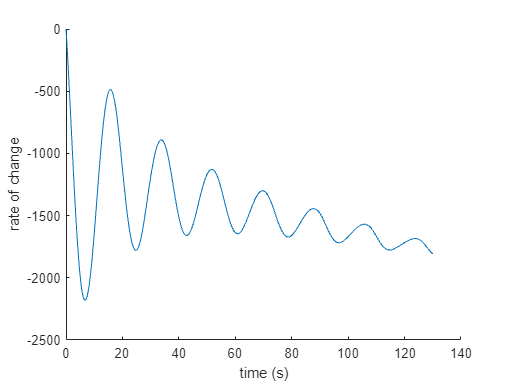


figure
hold on 
xlabel('time (s)')
ylabel('rate of change')
plot(t(1:end,:),x(1:end,8))

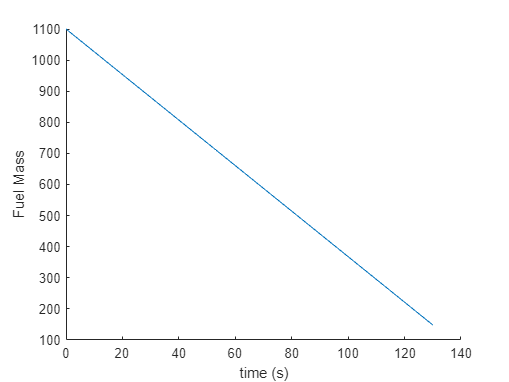

figure
hold on 
ylabel('Fuel Mass')
xlabel('time (s)')
plot(t(1:end,:),x(1:end,1)) %mass
hold off

figure
hold on 
ylabel('Fuel Mass with respect to time ')
xlabel('time (s)')
plot(t(1:end,:),x(1:end,2)) % rate of mass change
hold off

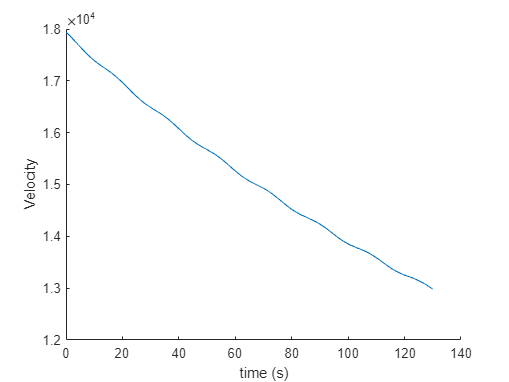

figure
hold on 
ylabel('Velocity')
xlabel('time (s)')
plot(t(1:end,:),x(1:end,3)) % velocity
hold off

plot(t(1:end,:),x(1:end,4)) % rate of change

plot(t(1:end,:),x(1:end,5))

plot(t(1:end,:),x(1:end,6))

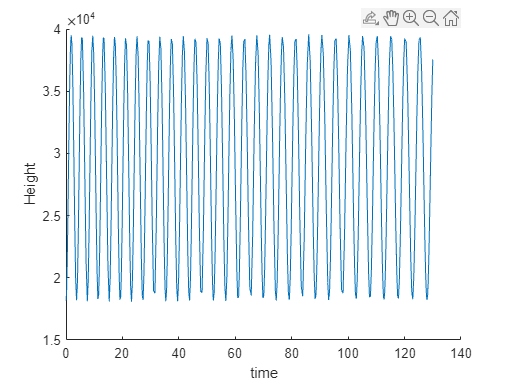

figure 
hold on
xlabel('time')
ylabel('Height')
plot(t(1:end,:),x(1:end,7))
hold off

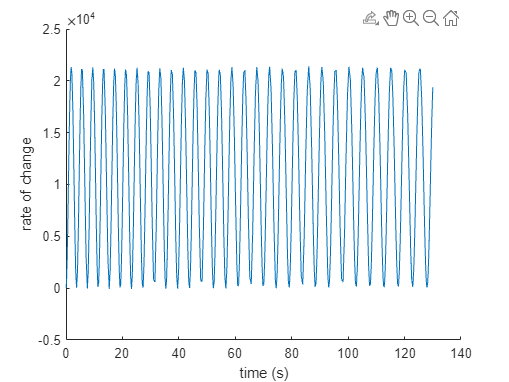

figure

hold on 
xlabel('time (s)')
ylabel('rate of change')
plot(t(1:end,:),x(1:end,8))